# Sample 6-3

## 標本化

二変量ダウンサンプリング

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Sampling

Bivariate downsampling

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

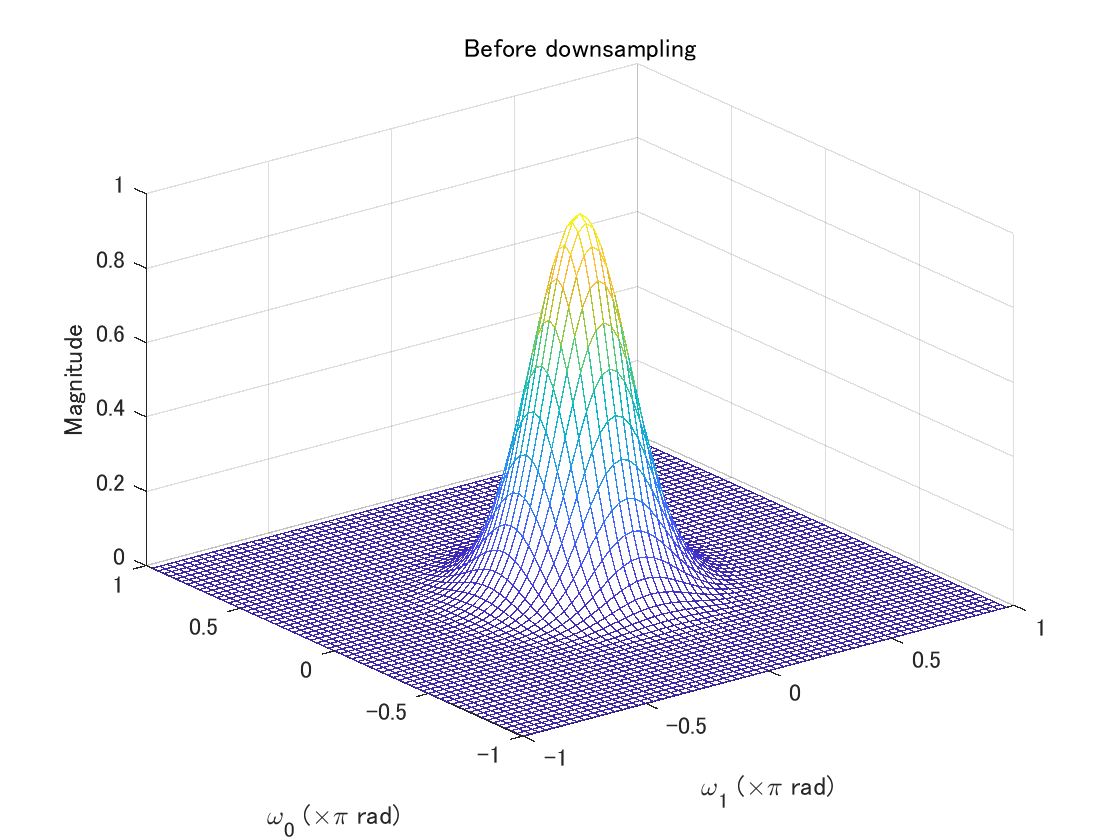

%% パラメータ設定
% 垂直の間引き率
verticalDecFactor = 2;
% 水平の間引き率
horizontalDecFactor = 3;

% 配列の標準偏差
sigma = 2;
% 配列のサイズ
sizeX = 31;

%% 2次元ガウス関数による配列の生成
arrayX = fspecial('gaussian',sizeX,sigma);

%% 原信号の周波数振幅特性
figure(1)
freqz2(arrayX)
xlabel('\omega_1 (\times\pi rad)')
ylabel('\omega_0 (\times\pi rad)')
title('Before downsampling')

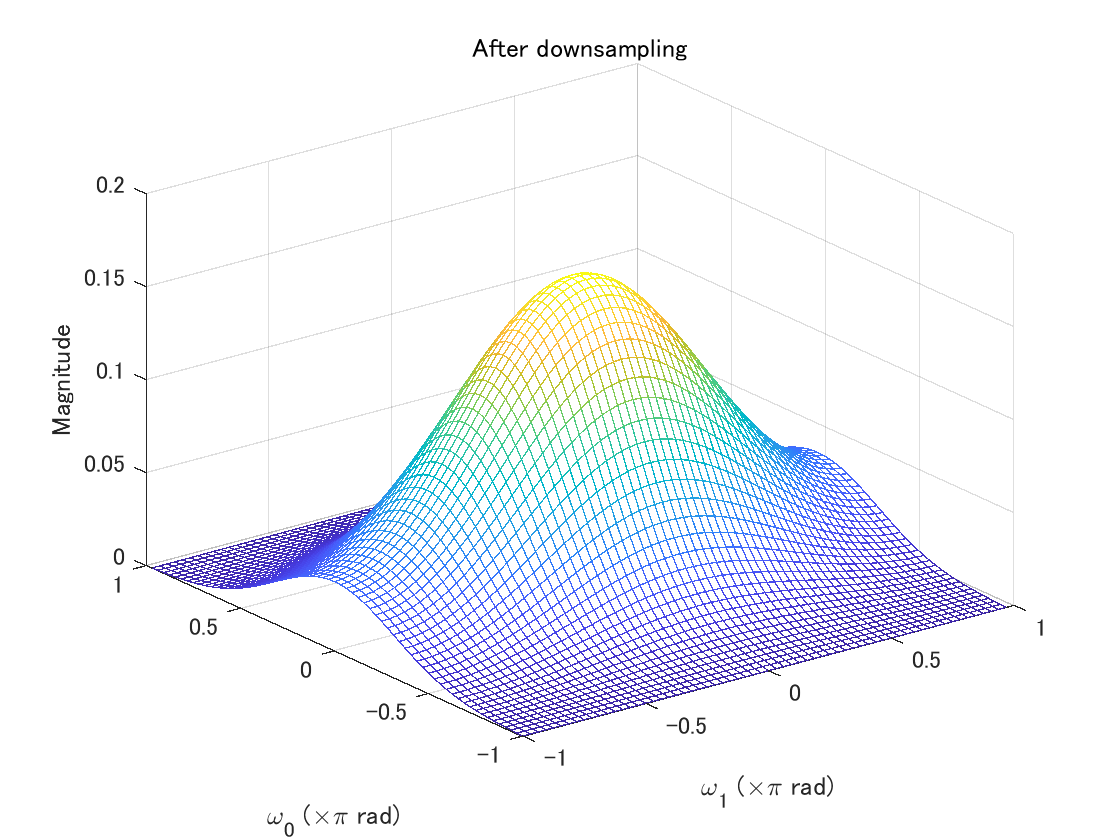

%% ダウンサンプリング
arrayY = ...
    downsample(...
        downsample(arrayX,...
            verticalDecFactor).',...
            horizontalDecFactor).';

%% 処理後の周波数振幅特性
figure(2)
freqz2(arrayY)
xlabel('\omega_1 (\times\pi rad)')
ylabel('\omega_0 (\times\pi rad)')
title('After downsampling')

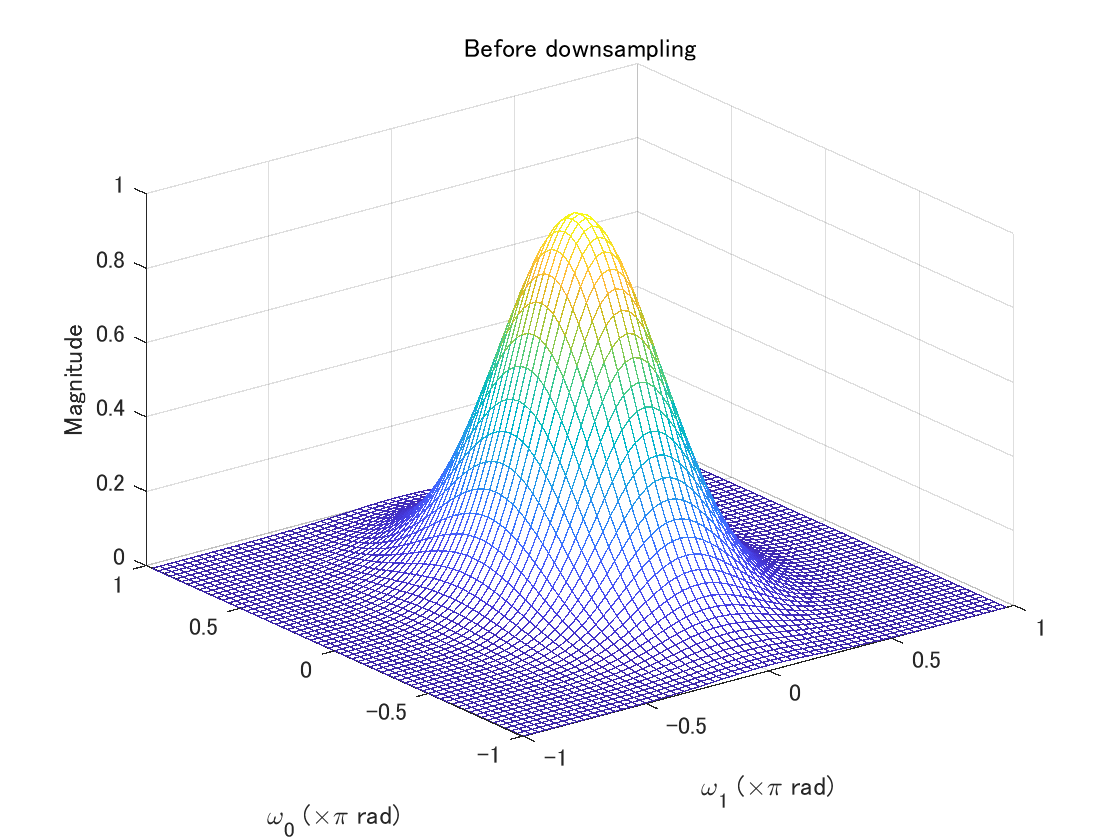

%% パラメータ設定
% 間引き行列（2x2)
downMtx = [ 1 1 ; -1 1 ];

% 配列の共分散行列
covMtx  = [2 0 ; 0 1];
% 配列のサイズ
sizeX = 31;

%% 2次元ガウス関数による配列の生成
arrayX = mygaussian2(sizeX,covMtx);

%% 原信号の周波数振幅特性
figure(1)
freqz2(arrayX)
xlabel('\omega_1 (\times\pi rad)')
ylabel('\omega_0 (\times\pi rad)')
title('Before downsampling')

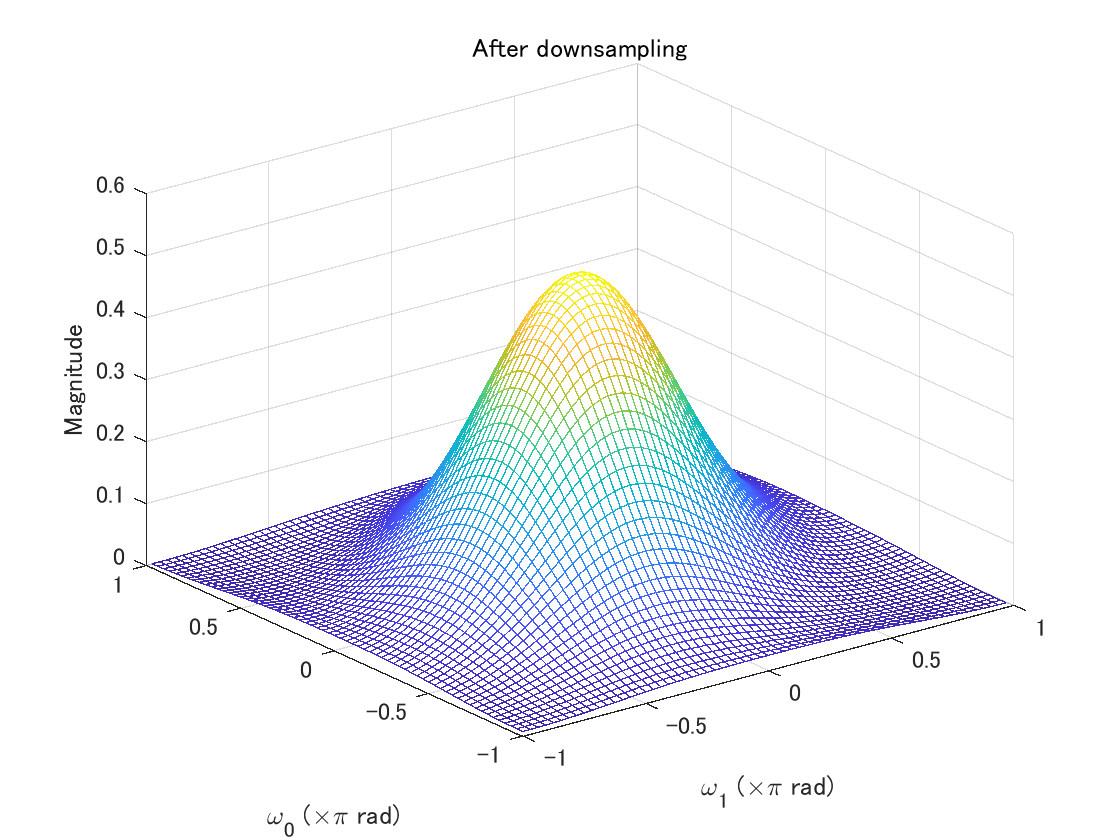

%% 2次元ダウンサンプリング
arrayY = downsample2(arrayX,downMtx);

%% 処理後の周波数振幅特性
figure(2)
freqz2(arrayY)
xlabel('\omega_1 (\times\pi rad)')
ylabel('\omega_0 (\times\pi rad)')
title('After downsampling')

### 関数の定義

function x = mygaussian2(sizeX, covMtx)
% GAUSSIAN2CQ
%
% Inputs
%
%   sizeX: size of output array 
%   covMtx: covariance matrix
%
% Output
%
%   x: array generated by Gauss Func. 
%
sizeHalf = floor(sizeX / 2);

if isscalar(covMtx)
    covMtx = covMtx * eye(2);
end

x = zeros(sizeHalf*2);
iRow = 1;
for n1 = -sizeHalf:sizeHalf
    iCol = 1;
    for n0 = -sizeHalf:sizeHalf    
        p = - 0.5 * [ n0 n1 ] * (covMtx\[ n0 n1 ].');
        x(iRow,iCol) = exp(p);
        iCol = iCol + 1;
    end
    iRow = iRow + 1;
end
x = x / sum(sum(x));

end % of gaussian2cq

function [outputArray, X, Y] = downsample2(inputArray,downMtx,phase)
%
% Inputs
%
%   inputArray: input array
%   downMtx:    downsampling matrix
%   phase:      downsampling phase
%
% Outputs
% 
%   outputArray: output array
%   X          : horizontal sampling points
%   Y          : vertical sampling points
%
% Copyright (C) 2006-2015 Shogo MURAMATSU, All rights reserved
%
if nargin < 3
    phase = [0 0].';
else
    phase = phase(:);
end

% 入力配列のサイズ
nRowsInputArray = size(inputArray,1);
nColsInputArray = size(inputArray,2);
nCompInputArray = size(inputArray,3);

% ダウンサンプリング後の配列範囲計算
vertexPoints(:,1) = [ 0 0 ].';
vertexPoints(:,2) = downMtx \ [ 0 nColsInputArray-1 ].';
vertexPoints(:,3) = downMtx \ [ nRowsInputArray-1 0 ].';
vertexPoints(:,4) = downMtx \ [ nRowsInputArray-1 nColsInputArray-1 ].';
minPoint = floor(min(vertexPoints,[],2));
maxPoint = ceil(max(vertexPoints,[],2));

% 間引き位相の FPD(downMtx)内への変換
phase = phase - downMtx * floor(downMtx \ phase);

% ダウンサンプリング
clear arrayY;
iRow = 1;
for m0 = minPoint(1):maxPoint(1)
    iCol = 1;
    for m1 = minPoint(2):maxPoint(2)
        originalPoint = downMtx * [ m0 m1 ].';
        n0 = originalPoint(1) + phase(1);
        n1 = originalPoint(2) + phase(2);
        if n0 >= 0 && n0 < nRowsInputArray  && ...
                n1 >= 0 && n1< nColsInputArray
            outputArray(iRow, iCol, :) = inputArray(n0 + 1, n1 + 1, :);            
        else
            outputArray(iRow, iCol, :) = zeros(1,nCompInputArray,...
                'like',inputArray);
        end
       iCol = iCol + 1;
    end
    iRow = iRow + 1;
end

Y = minPoint(1):maxPoint(1);
X = minPoint(2):maxPoint(2);

end

© Copyright, Shogo MURAMATSU, All rights reserved.